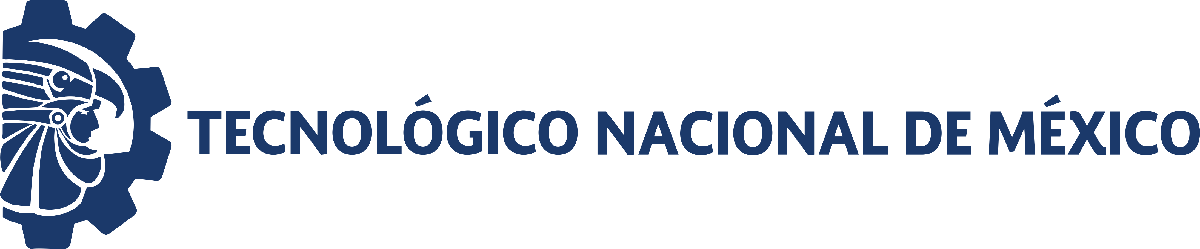                                 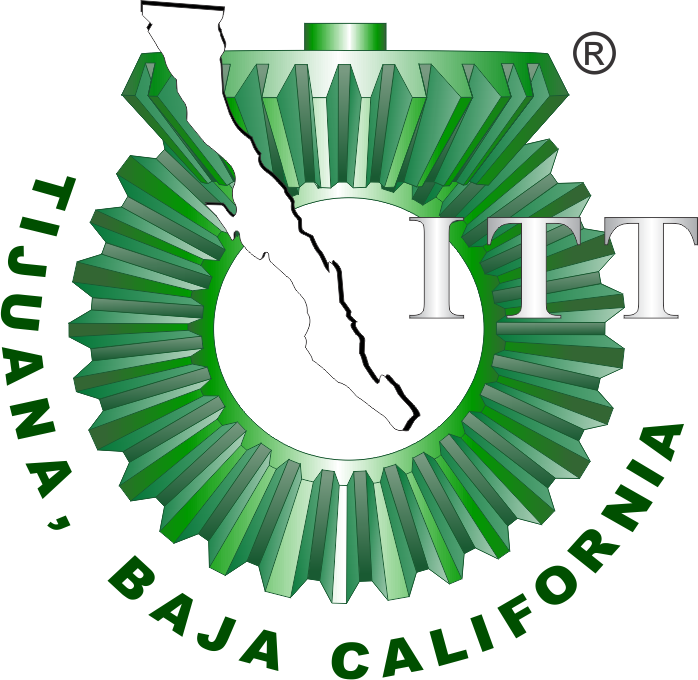

# Práctica tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica **

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

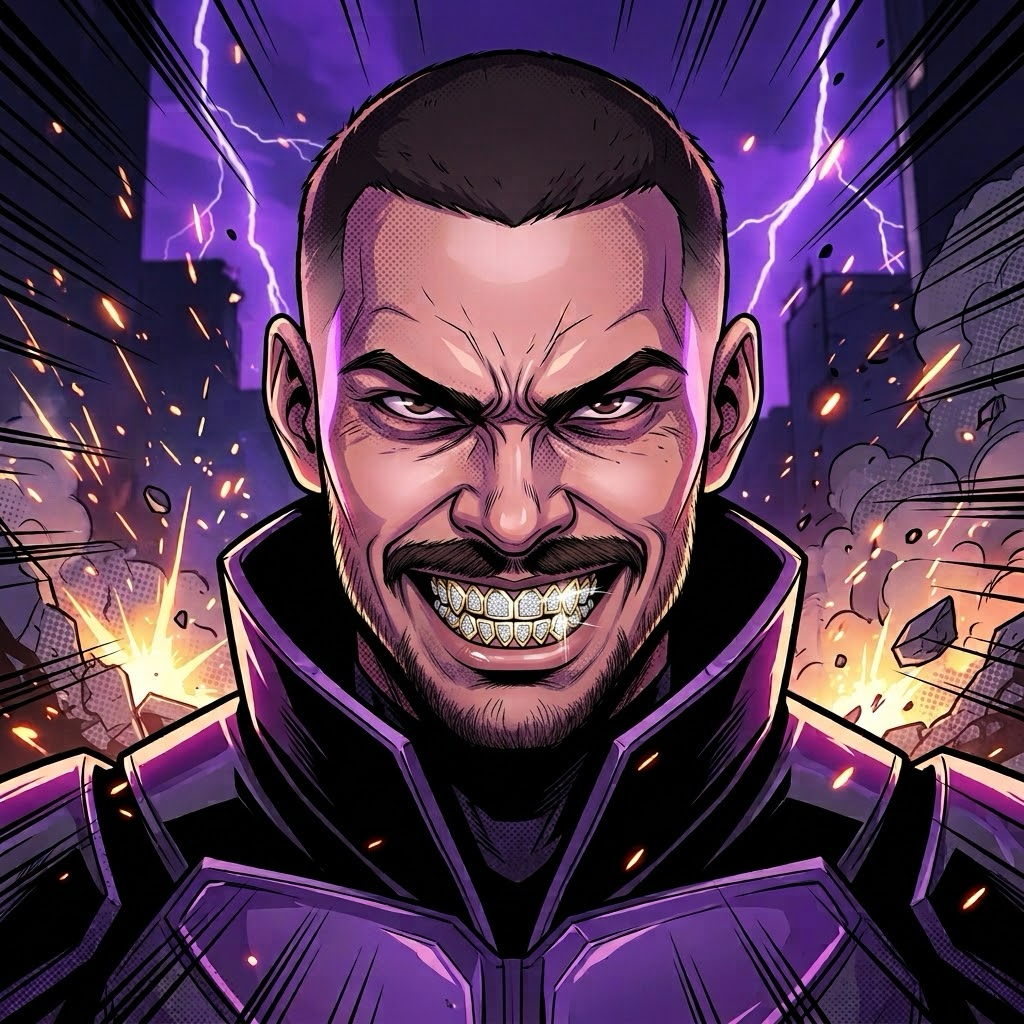

Nombre del alumno: Emilisno Villalobos García

Número de control: 23212243

Correo institucional: l23212243**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
open_system('Sistema1')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistema1', parameters);

## Respuesta al impulso unitario

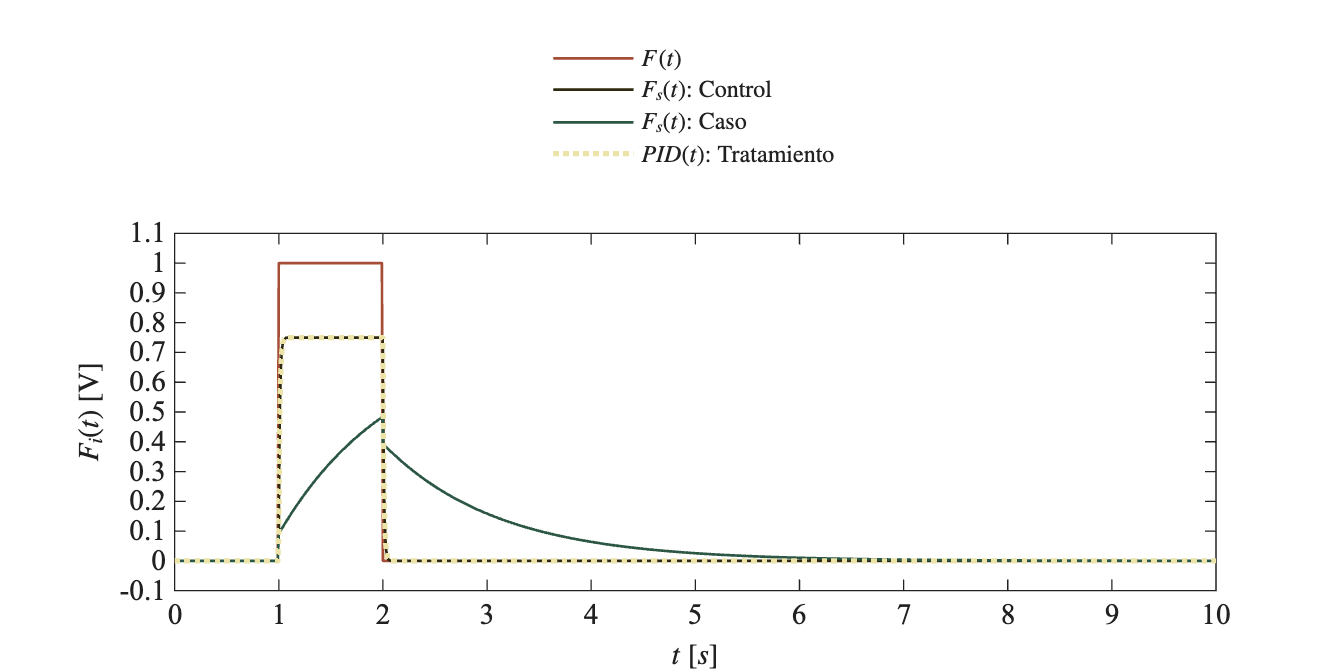

X = sim(Sistema1,parameters);
plotsignals(X.t,X.F,X.Fsx,X.Fsy,X.PID,'simulink')

## Modelo de EDOs

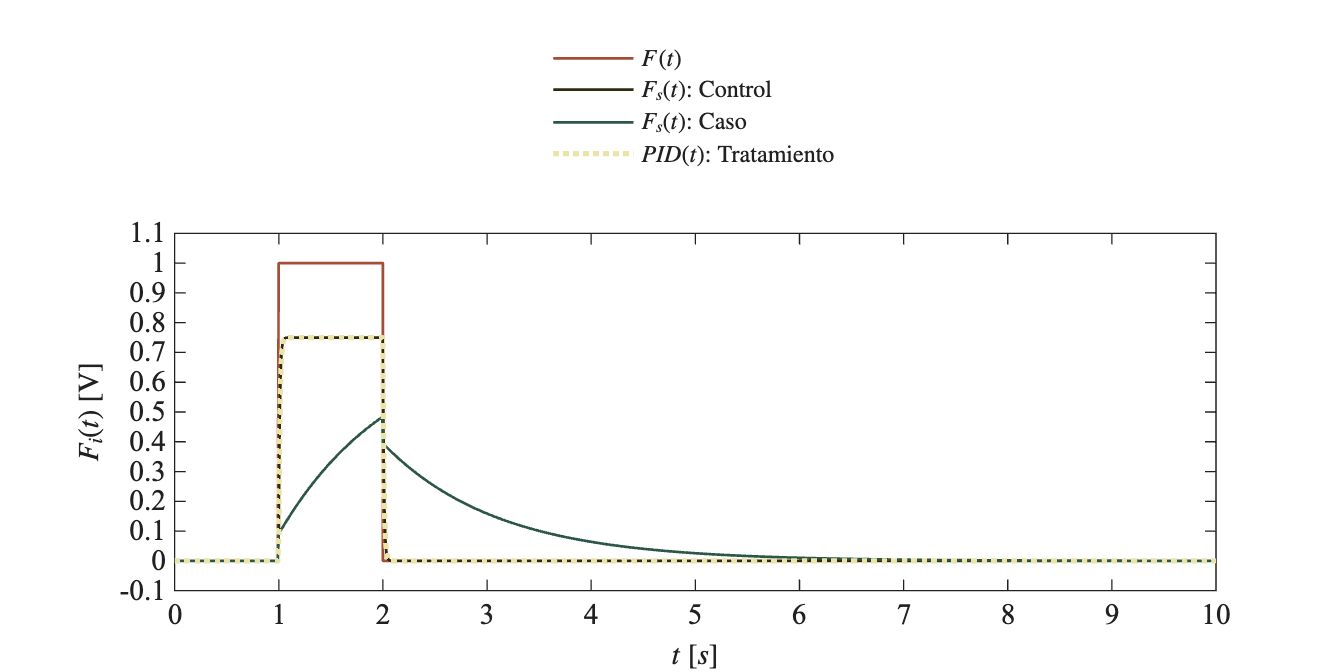

dt = 1e-3;
t = (0:dt:10)';
F = zeros(length(t),1); F(1/dt:2/dt) = 1;
PID = interp1(X.t, X.PID, t, 'previous');

par_control = [0.25,10e-6,100e-6,100];
par_caso    = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso    = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys')

function Fs = musculoesqueletico(par,F,t)
alpha = par(1); Cs = par(2); Cp= par(3); R = par(4); dt = t(2);
n = round(t(end)/dt);
x = zeros(length(t),1); x(1) = 0;
Fs = zeros (length(t),1); Fs(1) = 0;
for i = 1:n
    x(i+1) = x(i) + ((F(i)-x(i))/(R*(Cp+Cs)))*dt; %EDO
    Fs(i+1) = Cs*F(i)/(Cp+Cs) + (1 - alpha - Cs/(Cp+Cs))*x(i); %Función
end
end

## Función: Respuesta

function plotsignals(t,F,Fx,Fy,PID,caso)
    set (figure(), 'color', 'w')
    set (gcf, 'units', 'inches', 'position',[1,1,7,3.5])
    set (gca, 'fontname', 'times new roman','fontsize',11)
    hold on; grid off; box on;

    clr1 = [46, 41, 16]/255;
    clr2 = [44, 87, 69]/255;
    clr3 = [235, 227, 167]/255;
    clr4 = [166, 77, 55]/255;

    plot(t,F, '-', 'LineWidth', 1, 'Color',clr4)
    plot(t,Fx, '-', 'LineWidth', 1, 'Color',clr1)
    plot(t,Fy, '-', 'LineWidth', 1, 'Color',clr2)
    plot(t,PID, ':', 'LineWidth', 2, 'Color',clr3)

    L = legend('$F(t)$','$F_s(t)$: Control','$F_s(t)$: Caso','$PID(t)$: Tratamiento');
    set(L,'interpreter','latex','FontSize',9,'Location','northoutside','orientation','Vertical','Box','OFF')

    xlabel('$t$ $[s]$','interpreter','latex','FontSize',11)
    ylabel('$F_i(t)$ [V]', 'interpreter', 'latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10)
    ylim([-0.1,1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,['matlab',caso,'.pdf'],'ContentType','vector')
end